# Invasión Zombie

# Introducción

A lo largo de este taller, nuestro objetivo ha sido explorar y comprender la resolución de ecuaciones diferenciales mediante el uso de MATLAB, centrándonos en sistemas epidemiológicos y de propagación de enfermedades. En este proceso, hemos analizado cómo varios parámetros y condiciones iniciales afectan la dinámica de la propagación de una enfermedad en una población. Utilizando las herramientas de MATLAB, hemos resuelto ecuaciones diferenciales que describen la interacción entre suceptibles, infectados, recuperados y vacunados en un contexto de epidemia.

Durante nuestras soluciones, hemos examinado cómo factores como la tasa de transmisión, la tasa de recuperación, la tasa de vacunación y las condiciones iniciales de la población influyen en la propagación de la enfermedad. Además, hemos explorado cómo se pueden utilizar estas ecuaciones diferenciales para tomar decisiones informadas y estratégicas en la gestión de una epidemia. En última instancia, esta experiencia nos ha proporcionado una comprensión más profunda de cómo se modela matemáticamente la propagación de enfermedades y cómo las decisiones y políticas de salud pública pueden influir en el curso de una epidemia.

# Metodología

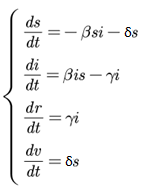

La metodología seguida en este estudio se enfoca en analizar y comprender un modelo epidemiológico de propagación de una pandemia zombie mediante la resolución de ecuaciones diferenciales y la utilización de MATLAB para visualizar los resultados. A continuación, se detallan los pasos de la metodología empleada:

#### A) Definición de Parámetros y Ecuaciones Diferenciales:

Comenzamos por establecer los parámetros clave del modelo epidemiológico, que incluyen la tasa de transmisión (Beta), la tasa de vacunación (Delta), la tasa de recuperación (Gama), así como las condiciones iniciales de suceptibles, infectados, recuperados y vacunados. Formulamos las ecuaciones diferenciales que describen la dinámica de este sistema epidemiológico, teniendo en cuenta cómo estos parámetros y condiciones iniciales afectan la propagación de la enfermedad.

#### B) Resolución de las Ecuaciones Diferenciales con MATLAB:

Utilizamos MATLAB para resolver las ecuaciones diferenciales del modelo epidemiológico. Durante este proceso, ajustamos los valores de los parámetros y condiciones iniciales según los escenarios que deseamos explorar. MATLAB nos permite obtener soluciones simbólicas y numéricas, lo que facilita la comprensión de cómo evoluciona la pandemia zombie en diferentes situaciones.

#### C) Visualización y Graficación de los Resultados:

Representamos gráficamente las soluciones obtenidas para suceptibles, infectados, recuperados y vacunados a lo largo del tiempo. Estos gráficos nos permiten visualizar cómo se desarrolla la pandemia zombie en función de los parámetros y condiciones iniciales seleccionados. Interpretamos los resultados y analizamos las tendencias observadas en los gráficos.

#### D) Análisis e Interpretación:

Llevamos a cabo un análisis detallado de los resultados obtenidos. Interpretamos el comportamiento del modelo epidemiológico en diferentes escenarios, identificando características clave en los gráficos y relacionándolas con los valores de los parámetros. Analizamos cómo cambios en Beta, Delta, Gama y las condiciones iniciales afectan la propagación de la enfermedad.

#### E) Conclusiones y Respuestas a Preguntas Clave:

Finalmente, concluimos el estudio proporcionando insights sobre cómo los valores de los parámetros pueden influir en el comportamiento de la pandemia zombie. Respondemos preguntas como "¿Qué sucede si aumentamos la tasa de vacunación?" o "¿Cómo afecta una mayor tasa de transmisión al número de infectados?". Estas conclusiones nos ayudan a comprender mejor cómo tomar decisiones estratégicas en la gestión de una epidemia zombie y aplicar conceptos de modelado epidemiológico en situaciones de la vida real

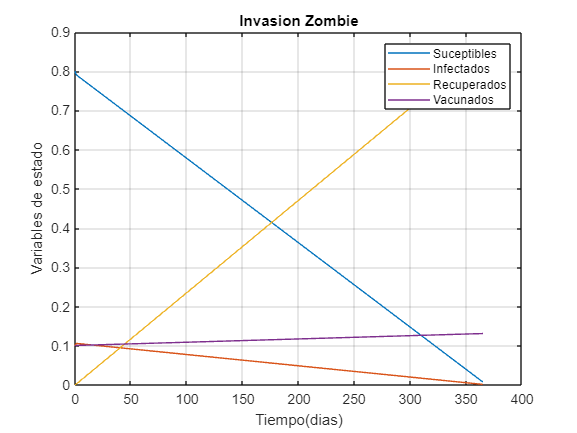

%Tenemos una poblacion del 100% con S, i, R, V

%Defino las variables de estado

syms s(t) i(t) r(t) v(t);


%Coeficientes o constantes del sistema

Beta = 0.1;  %Tasa de transmision de la enfermedad
Delta = 0.001; %Tasa de vacunacion
Gama = 0.02; %Tasa de recuperacion y aislamiento



%Espacio de muestreo para la invasion zombie
Ts = 1; %Tiempo de muestre en un dia
tmin = 0;
tmax = 365; %La enfermedad zombie en un año
tspan = [tmin,Ts,tmax];


%Defino las ecuaciones de estado para la invasion zonbie
%Tasa de suceptibles zombies
dsZombies = diff(s,t,1);
%Tasa de infectados zombies
diZombies = diff(i,t,1);
%Tasa de recuperados zombies
drZombies = diff(r,t,1);
%Tasa de vacunados contra zombies
dvZombies = diff(v,t,1);



% Define las tasas de cambio como funciones anónimas
tasa_suceptibles_Zombies = @(t, s, i, r, v) -Beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v) Beta * i * s - Gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v) Gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v) Delta * s;

% Crea la función de estado
Funciones_estado = @(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4))];

% Condiciones iniciales
s0 = 0.8;
i0 = 0.1;
r0 = 0;
v0 = 0.1;

% Vector de condiciones iniciales
C_iniciales_Zombies = [s0; i0; r0; v0];

% Resolver el sistema de ecuaciones diferenciales
[tiempo, Salida] = ode45(Funciones_estado, tspan, C_iniciales_Zombies);

% Ahora podemos analizar los resultados en la matriz Y y el vector t.



%Usamos el comanod ODE45     para resolver


%Solucionamos
%Graficamos la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel("Tiempo(dias)");
ylabel("Variables de estado");
title("Invasion Zombie")
legend("Suceptibles","Infectados", "Recuperados", "Vacunados")

#### Interpretaremos las tasas de cambio

### Suceptibles

La primera parte (-Beta * s * i) describe la disminución de suceptibles debido a la transmisión de la enfermedad desde los infectados a los suceptibles mientra la la segunda parte (-Delta * s) representa la disminución de suceptibles debido a la vacunación.

### Infectados

La primera parte (Beta * i * s) indica el aumento de infectados debido a la transmisión de la enfermedad desde los suceptibles a los infectados y la segunda parte (-Gama * i) describe la disminución de infectados debido a la recuperación y aislamiento.

### Recuperados

Los recuperados aumentan a una tasa igual a (Gama * i), ya que los infectados se recuperan y dejan de estar infectados

### Vacunados

Los vacunados aumentan a una tasa igual a (Delta * s), ya que las personas susceptibles se vacunan y pasan a ser vacunada

# Pregunta 1

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

%Tenemos una poblacion del 100% con S, i, R, V

%Defino las variables de estado

syms s(t) i(t) r(t) v(t);


%Coeficientes o constantes del sistema

Beta = 0.1;  %Tasa de transmision de la enfermedad
Delta = 0.01; %Tasa de vacunacion
Gama = 0.02; %Tasa de recuperacion y aislamiento


%Espacio de muestreo para la invasion zombie
Ts = 1; %Tiempo de muestre en un dia
tmin = 0;
tmax = 365; %La enfermedad zombie en un año
tspan = [tmin,Ts,tmax];



% Define las tasas de cambio como funciones anónimas
tasa_suceptibles_Zombies = @(t, s, i, r, v) -Beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v) Beta * i * s - Gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v) Gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v) Delta * s;

% Crea la función de estado
Funciones_estado = @(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4))];

% Condiciones iniciales
s0 = 0.8;
i0 = 0.1414;
r0 = 0;
v0 = 0.0586;

% Vector de condiciones iniciales
C_iniciales_Zombies = [s0; i0; r0; v0];

% Resolver el sistema de ecuaciones diferenciales
[tiempo, Salida] = ode45(Funciones_estado, tspan, C_iniciales_Zombies);

% Encuentra el valor máximo de la variable "Infectados"
max_infectados = max(Salida(:, 2));

% Muestra el valor máximo en la ventana de comandos
fprintf('El valor máximo de "Infectados" es: %.4f\n', max_infectados);

El valor máximo de "Infectados" es: 0.1500


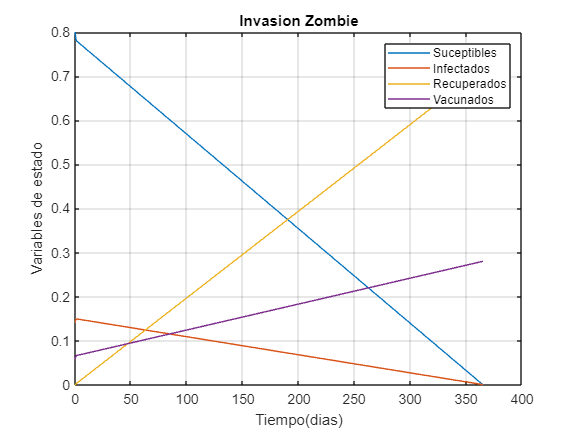


%Solucionamos
%Graficamos la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel("Tiempo(dias)");
ylabel("Variables de estado");
title("Invasion Zombie")
legend("Suceptibles","Infectados", "Recuperados", "Vacunados")

Como vimos anteriormente bajo esas constantes, el porcentaje minimo de vacunados que deberia haber para que el pico maximo que tome los infectados en los primeros dias sea de 0.15 es del 5.86% de las personas deben estar vacunadas y con una cantidad de infectados cercanas al numero del 15% de la población.

#### Otra forma de verlo

Si queremos analizarlo de otra forma y que los infectados nos de un porcentaje maximo de 0.15 pero con una pandemia en decadencia podemos analizar el siguiente codigo

% Ajusta las condiciones iniciales para que la suma sea igual a 1
s0 = 0; % Porcentaje inicial de susceptibles (80%)
i0 = 0.15; % Porcentaje inicial de infectados (15%)
r0 = 0;    % Porcentaje inicial de recuperados (en este caso, 0)
v0 = 1 - s0 - i0 - r0; % Porcentaje inicial de vacunados para que la suma sea 1

% Vector de condiciones iniciales
C_iniciales_Zombies = [s0; i0; r0; v0];

% Resolver el sistema de ecuaciones diferenciales
[tiempo, Salida] = ode45(Funciones_estado, tspan, C_iniciales_Zombies);

% Encuentra el valor máximo de la variable "Infectados"
max_infectados = max(Salida(:, 2));

% Muestra el valor máximo en la ventana de comandos
fprintf('El valor máximo de "Infectados" es: %.4f\n', max_infectados);

El valor máximo de "Infectados" es: 0.1500


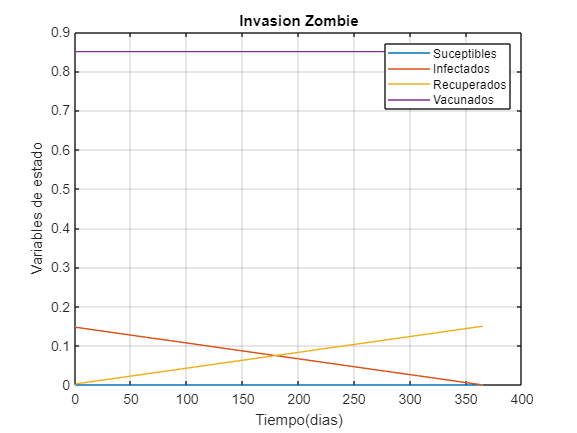


%Solucionamos
%Graficamos la solucion
figure
plot(tiempo,Salida)
grid on
hold on
xlabel("Tiempo(dias)");
ylabel("Variables de estado");
title("Invasion Zombie")
legend("Suceptibles","Infectados", "Recuperados", "Vacunados")

En este caso la solucion nos da exactamente 0.15 como maximo puesto que los vacunados se mantendran constantes en el tiempo ya que los suceptibles empezaran siendo 0, por lo que los vacunados no cambiaran, y solo abra cambios entre los "infectados" y los "recuperados" que ya no volveran a ser infectados, teniendo una pandemia de zombie que decrecera en el tiempo.

# Pregunta 2

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

% Coeficientes o constantes del sistema
Beta = 0.1;  % Tasa de transmisión de la enfermedad
Delta = 0.01; % Tasa de vacunación
Gama = 0.02; % Tasa de recuperación y aislamiento

% Espacio de muestreo para la invasión zombie
Ts = 0.1; % Tiempo de muestreo mas preciso
tmin = 0;
tmax = 365; % La enfermedad zombie en dias
tspan = [tmin, Ts, tmax];

% Define las tasas de cambio como funciones anónimas
tasa_suceptibles_Zombies = @(t, s, i, r, v) -Beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v) Beta * i * s - Gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v) Gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v) Delta * s;

% Crea la función de estado
Funciones_estado = @(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4));
                            tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4))];

% Valores iniciales para i(0) (al menos 5 valores diferentes)
i0_values = [0.005, 0.1, 0.15, 0.25, 0.7];

% Inicializa una matriz para almacenar las soluciones de i(t) con diferentes i(0)
soluciones_i_t = zeros(length(i0_values), length(tspan));

% Resuelve el sistema de ecuaciones diferenciales para cada valor de i(0)
for k = 1:length(i0_values)
    % Ajustar las condiciones iniciales para el valor actual de i(0)
    i0 = i0_values(k);
    v0 = 0.1;
    s0 = 1 - i0-v0 % Asegura que la suma de condiciones iniciales sea 1
    C_iniciales_Zombies = [s0; i0; 0; v0];
    
    % Resuelve el sistema de ecuaciones para este conjunto de condiciones iniciales
    [tiempo, Salida] = ode45(Funciones_estado, tspan, C_iniciales_Zombies);
    
    % Almacena la solución de i(t) en la matriz de soluciones
    soluciones_i_t(k, :) = Salida(:, 2); % La segunda columna contiene i(t)
end

s0 = 0.8950

s0 = 0.8000

s0 = 0.7500

s0 = 0.6500

s0 = 0.2000

%Podemos observar como los suceptibles cambian a medida que cambia i(o)
%esto es debido porque la poblacion debe dar 1 o 100%
% Graficar las soluciones de i(t) con diferentes i(0)
figure;
for k = 1:length(i0_values)
    plot(tiempo, soluciones_i_t(k, :), 'DisplayName', ['i(0) = ', num2str(i0_values(k))]);
    hold on;
    max(soluciones_i_t(k, :))
end

ans = 0.0050

ans = 0.1006

ans = 0.1508

ans = 0.2511

ans = 0.7000

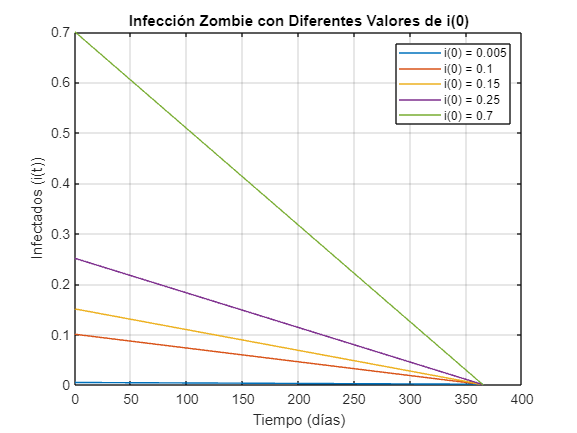

grid on;
xlabel("Tiempo (días)");
ylabel("Infectados (i(t))");
title("Infección Zombie con Diferentes Valores de i(0)");
legend('Location', 'northeast');

#### Analisis

En el análisis del gráfico anterior, podemos apreciar una relación crítica entre la dinámica de los infectados y la proporción inicial de suceptibles en la población. Esta relación se debe a que la cantidad de suceptibles actúa como un factor determinante en la propagación de la enfermedad. Cuando los suceptibles representan el 20% de la población inicial, esto indica un escenario en el que (la tasa de transmisión de la enfermedad (Beta) multiplicada por la proporción de suceptibles iniciales) es menor que la tasa de recuperación (Gama), lo que significa que la tasa de recuperación supera a la tasa de infección. Como resultado, la enfermedad comienza a declinar rápidamente, como se evidencia en la disminución de los infectados iniciales, que eran el 70% de la población.

Sin embargo, en situaciones en las que los infectados iniciales representan un porcentaje muy bajo de la población, como el 0.005 o 0.5%, los suceptibles constituyen la gran mayoría, alrededor del 89.5%. En este caso, la propagación de la enfermedad ocurre de manera más acelerada, ya que la tasa de infección supera significativamente la tasa de recuperación. Esto se refleja en el aumento exponencial de los infectados, como se observa en los máximos alcanzados en los otros gráficos. En resumen, estos resultados subrayan que solo cuando la proporción de suceptibles es menor al 20% se produce una rápida disminución de la enfermedad, mientras que en otros casos, la enfermedad tiende a aumentar en sus primeras etapas.

# Pregunta 3

Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

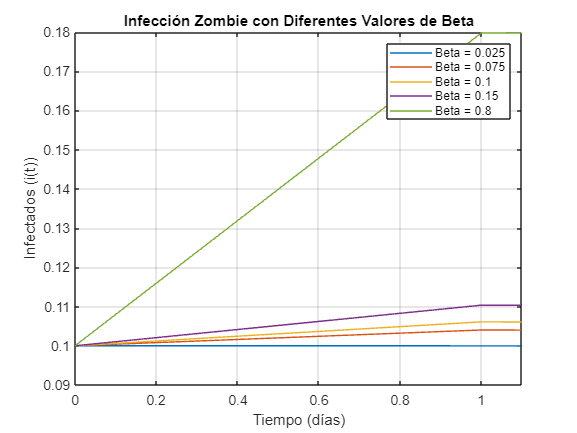

% Coeficientes o constantes del sistema (inicialmente, Beta es un valor base)
Beta_base = 0.1;  % Tasa de transmisión de la enfermedad base
Delta = 0.01;     % Tasa de vacunación
Gama = 0.02;      % Tasa de recuperación y aislamiento

% Valores de Beta para evaluar (al menos 5 valores diferentes)
beta_values = [0.025, 0.075, 0.1, 0.15, 0.8];

% Espacio de muestreo para la invasión zombie
Ts = 1;           % Tiempo de muestreo en un día
tmin = 0;
tmax = 365;       % La enfermedad zombie en un año
tspan = [tmin, Ts, tmax];

% Define las tasas de cambio como funciones anónimas con Beta variable
tasa_suceptibles_Zombies = @(t, s, i, r, v, beta) -beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v, beta) beta * i * s - Gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v, beta) Gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v, beta) Delta * s;

% Inicializa una matriz para almacenar las soluciones de i(t) con diferentes valores de Beta
soluciones_i_t = zeros(length(beta_values), length(tspan));

% Resuelve el sistema de ecuaciones diferenciales para cada valor de Beta
for k = 1:length(beta_values)
    % Ajusta Beta para el valor actual
    Beta = beta_values(k);
    
    % Condiciones iniciales (mantenemos las mismas condiciones iniciales)
    s0 = 0.8;
    i0 = 0.1;
    r0 = 0;
    v0 = 0.1;
    C_iniciales_Zombies = [s0; i0; r0; v0];
    
    % Resuelve el sistema de ecuaciones para este valor de Beta
    [tiempo, Salida] = ode45(@(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4), Beta)], ...
                                      tspan, C_iniciales_Zombies);
    
    % Almacena la solución de i(t) en la matriz de soluciones
    soluciones_i_t(k, :) = Salida(:, 2); % La segunda columna contiene i(t)
end

% Graficar las soluciones de i(t) con diferentes valores de Beta
figure;
for k = 1:length(beta_values)
    plot(tiempo, soluciones_i_t(k, :), 'DisplayName', ['Beta = ', num2str(beta_values(k))]);
    hold on;
end
grid on;
xlabel("Tiempo (días)");
ylabel("Infectados (i(t))");
title("Infección Zombie con Diferentes Valores de Beta");
legend('Location', 'northeast');
xlim([0,1.1])


% Identificar el valor máximo de Beta que evitaría una epidemia
valor_maximo_evitar_epidemia = [];
for k = 1:length(beta_values)
    if all(soluciones_i_t(k, :) <= 0.1)
        valor_maximo_evitar_epidemia = beta_values(k);
        break; % Romper el bucle cuando se cumple la condición
    end
end

if isempty(valor_maximo_evitar_epidemia)
    fprintf('No se encontró un valor de Beta para evitar una epidemia.\n');
else
    fprintf('El valor máximo de Beta para evitar una epidemia es: %.4f\n', valor_maximo_evitar_epidemia);
end

El valor máximo de Beta para evitar una epidemia es: 0.0250


### Analisis de beta

La tasa de transmisión ($Beta$) en un modelo epidemiológico puede ser manipulada en la vida real a través de diversas medidas y estrategias. En primer lugar, se puede controlar Beta mediante la promoción de medidas de prevención, como el uso de mascarillas, el distanciamiento social y la higiene personal. Estas acciones reducen la probabilidad de transmisión de la enfermedad entre individuos, disminuyendo efectivamente el valor de $Beta$.

Además, la implementación de políticas de vacunación masiva puede tener un impacto significativo en la reducción de $Beta$. Al vacunar a una gran parte de la población, se disminuye la cantidad de personas susceptibles a la enfermedad, lo que reduce la tasa de transmisión. Esto se traduce en una reducción en el número de nuevos casos y, por lo tanto, en un menor valor de Beta

### Analisis de resultados

En el gráfico, observamos una tendencia general de aumento en el número de infectados a medida que transcurre el tiempo, lo que es típico en una epidemia. Sin embargo, el código de simulación revela un punto crucial: al establecer un valor específico de $Beta$ en 0.025, se alcanza un equilibrio entre la tasa de transmisión de la enfermedad (Beta) y la tasa de recuperación (Gama). Este equilibrio evita que la epidemia se propague de manera descontrolada, y en su lugar, la enfermedad comienza a declinar gradualmente. Este fenómeno se debe a que (Beta * S(0)) / Gama es menor o igual a 1 en esta configuración, cumpliendo con un requisito fundamental para que el número de infectados no aumente exponencialmente. Sin embargo, es importante destacar que si incrementamos el valor de Beta por encima de 0.025, la enfermedad se propaga a una velocidad mayor que la tasa de recuperación, lo que resulta en un aumento constante de los infectados, lo que podría conducir a una pandemia incontrolable.

# Pregunta 4

Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

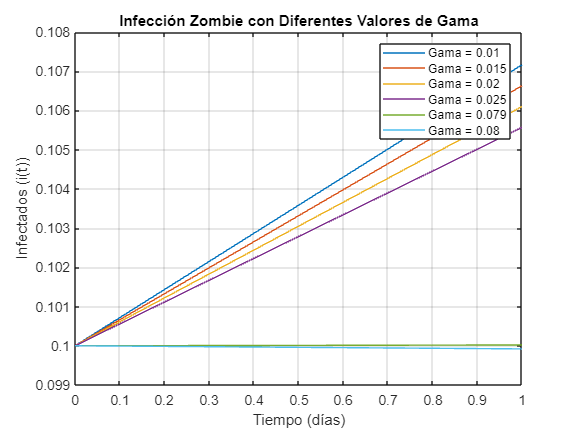

% Coeficientes o constantes del sistema (inicialmente, Gama es un valor base)
Beta = 0.1;         % Tasa de transmisión de la enfermedad
Delta = 0.01;       % Tasa de vacunación
Gama_base = 0.02;   % Tasa de recuperación y aislamiento base

% Valores de Gama para evaluar (al menos 5 valores diferentes)
gama_values = [0.01, 0.015, 0.02, 0.025, 0.079, 0.08];

% Espacio de muestreo para la invasión zombie
Ts = 1;           % Tiempo de muestreo en un día
tmin = 0;
tmax = 365;       % La enfermedad zombie en un año
tspan = [tmin, Ts, tmax];

% Define las tasas de cambio como funciones anónimas con Gama variable
tasa_suceptibles_Zombies = @(t, s, i, r, v, gama) -Beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v, gama) Beta * i * s - gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v, gama) gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v, gama) Delta * s;

% Inicializa una matriz para almacenar las soluciones de i(t) con diferentes valores de Gama
soluciones_i_t = zeros(length(gama_values), length(tspan));

% Resuelve el sistema de ecuaciones diferenciales para cada valor de Gama
for k = 1:length(gama_values)
    % Ajusta Gama para el valor actual
    Gama = gama_values(k);
    
    % Condiciones iniciales (mantenemos las mismas condiciones iniciales)
    s0 = 0.8;
    i0 = 0.1;
    r0 = 0;
    v0 = 0.1;
    C_iniciales_Zombies = [s0; i0; r0; v0];
    
    % Resuelve el sistema de ecuaciones para este valor de Gama
    [tiempo, Salida] = ode45(@(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4), Gama);
                                      tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4), Gama);
                                      tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4), Gama);
                                      tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4), Gama)], ...
                                      tspan, C_iniciales_Zombies);
    
    % Almacena la solución de i(t) en la matriz de soluciones
    soluciones_i_t(k, :) = Salida(:, 2); % La segunda columna contiene i(t)
end

% Graficar las soluciones de i(t) con diferentes valores de Gama
figure;
for k = 1:length(gama_values)
    plot(tiempo, soluciones_i_t(k, :), 'DisplayName', ['Gama = ', num2str(gama_values(k))]);
    hold on;
end
grid on;
xlabel("Tiempo (días)");
ylabel("Infectados (i(t))");
title("Infección Zombie con Diferentes Valores de Gama");
legend('Location', 'northeast');
xlim([0,1])

% Identificar el valor mínimo de Gama que evitaría una epidemia
valor_minimo_evitar_epidemia = [];
for k = 1:length(gama_values)
    if all(soluciones_i_t(k, :) <= 0.1)
        valor_minimo_evitar_epidemia = gama_values(k);
        break; % Romper el bucle cuando se cumple la condición
    end
end

if isempty(valor_minimo_evitar_epidemia)
    fprintf('No se encontró un valor de Gama para evitar una epidemia.\n');
else
    fprintf('El valor mínimo de Gama para evitar una epidemia es: %.4f\n', valor_minimo_evitar_epidemia);
end

El valor mínimo de Gama para evitar una epidemia es: 0.0800


### Analisis de gama

En la vida real, la variable `γ` puede ser influenciada por una serie de medidas tomadas por el gobierno y la población en general. Por ejemplo, si se implementan políticas de cuarentena más estrictas, $\gamma $ tiende a aumentar, ya que se reduce la interacción entre personas infectadas y susceptibles, acelerando así la recuperación. Del mismo modo, si la población comienza a tomar medidas de precaución de manera masiva, como el uso de mascarillas y el distanciamiento social, también se puede observar un aumento en $\gamma $.

Además, un incremento en `γ` puede interpretarse como una mejora en la eficiencia del sistema de atención médica del país y la disponibilidad de tratamientos efectivos. Cuando el sistema de salud es capaz de proporcionar una atención adecuada y los tratamientos son eficaces, los pacientes tienden a recuperarse más rápidamente, lo que se traduce en un valor más alto para $\gamma $

### Analisis de resultados

Como podemos observar en el código, este nos muestra que el valor mínimo de `γ` necesario para evitar una pandemia en este modelo matemático es de 0.08. Matemáticamente, este valor se puede calcular como $\gamma  = Beta * s0$. Esto se interpreta como que la tasa de aislamiento es mayor que la tasa a la que se propaga la enfermedad en relación con los susceptibles.

Para todos los valores en los que `γ` es menor a 0.08, podemos observar cómo la cantidad de infectados aumenta, en proporciones mayores o menores, dependiendo de cuán pequeño o grande sea $\gamma $

# Pregunta 5

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

% Coeficientes o constantes del sistema (inicialmente, Delta es un valor base)
Beta = 1;  % Tasa de transmisión de la enfermedad
Delta_base = 0.01;     % Tasa de vacunación base
Gama = 0.02;      % Tasa de recuperación y aislamiento

% Valores de Delta para evaluar (al menos 5 valores diferentes, uno de ellos igual a cero)
delta_values = [0, 0.00015, 0.01, 0.012, 0.105,0.106];

% Espacio de muestreo para la invasión zombie
Ts = 1;           % Tiempo de muestreo en un día
tmin = 0;
tmax = 200;       % La enfermedad zombie en un año
tspan = [tmin, Ts, tmax];

% Define las tasas de cambio como funciones anónimas con Delta variable
tasa_suceptibles_Zombies = @(t, s, i, r, v, beta) -beta * s * i - Delta * s;
tasa_infectados_Zombies = @(t, s, i, r, v, beta) beta * i * s - Gama * i;
tasa_recuperados_Zombies = @(t, s, i, r, v, beta) Gama * i;
tasa_vacunados_Zombies = @(t, s, i, r, v, beta) Delta * s;

% Inicializa una matriz para almacenar las soluciones de i(t) con diferentes valores de Delta
soluciones_i_t = zeros(length(delta_values), length(tspan));

% Resuelve el sistema de ecuaciones diferenciales para cada valor de Delta
for k = 1:length(delta_values)
    % Ajusta Delta para el valor actual
    Delta = delta_values(k);
    
    % Condiciones iniciales (mantenemos las mismas condiciones iniciales)
    s0 = 0.8;
    i0 = 0.1;
    r0 = 0;
    v0 = 0.1;
    C_iniciales_Zombies = [s0; i0; r0; v0];
    tasa_suceptibles_Zombies = @(t, s, i, r, v, beta) -beta * s * i - Delta * s;
    tasa_infectados_Zombies = @(t, s, i, r, v, beta) beta * i * s - Gama * i;
    tasa_recuperados_Zombies = @(t, s, i, r, v, beta) Gama * i;
    tasa_vacunados_Zombies = @(t, s, i, r, v, beta) Delta * s;
    %Resuelve el sistema de ecuaciones diferenciales para este valor de Delta
    [tiempo, Salida] = ode45(@(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                  tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                  tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                  tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4), Beta)], ...
                                  tspan, C_iniciales_Zombies);
    % Almacena la solución de i(t) en la matriz de soluciones
    soluciones_i_t(k, :) = Salida(:, 2); % La segunda columna contiene i(t)

    % Encuentra el valor máximo de i(t) para este valor de Delta

    max_i_t = max(soluciones_i_t(k, :));

    fprintf('Valor máximo de i(t) para Delta = %.4f: %.4f\n', delta_values(k), max_i_t);


    
    
    
    % Almacena la solución de i(t) en la matriz de soluciones
    soluciones_i_t(k, :) = Salida(:, 2); % La segunda columna contiene i(t)
end

Valor máximo de i(t) para Delta = 0.0000: 0.2075
Valor máximo de i(t) para Delta = 0.0001: 0.2075
Valor máximo de i(t) para Delta = 0.0100: 0.2068
Valor máximo de i(t) para Delta = 0.0120: 0.2066
Valor máximo de i(t) para Delta = 0.1050: 0.2000
Valor máximo de i(t) para Delta = 0.1060: 0.2000


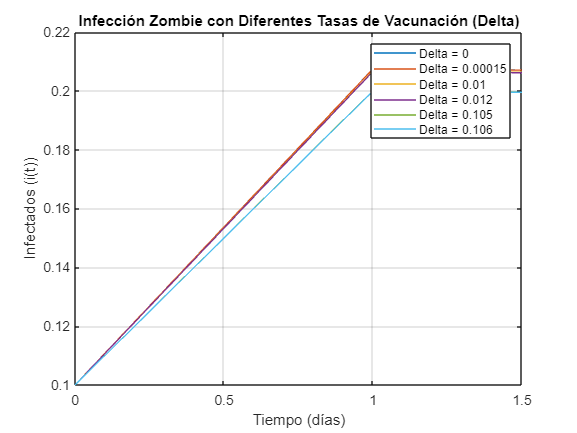


% Graficar las soluciones de i(t) con diferentes valores de Delta
figure;
for k = 1:length(delta_values)
    plot(tiempo, soluciones_i_t(k, :), 'DisplayName', ['Delta = ', num2str(delta_values(k))]);
    hold on;
end
grid on;
xlabel("Tiempo (días)");
ylabel("Infectados (i(t))");
title("Infección Zombie con Diferentes Tasas de Vacunación (Delta)");
legend('Location', 'northeast');
xlim([0,1.5])


% Identificar la tasa mínima de vacunación para que el pico de infectados llegue a 0.2 (aumento del 100%)
tasa_minima_vacunacion = [];
for k = 1:length(delta_values)
    if all(soluciones_i_t(k, :) <= 0.2)
        tasa_minima_vacunacion = delta_values(k);
        break; % Romper el bucle cuando se cumple la condición
    end
end

if isempty(tasa_minima_vacunacion)
    fprintf('No se encontró una tasa de vacunación para lograr el aumento del 100%% en el pico de infectados.\n');
else
    fprintf('La tasa mínima de vacunación para lograr un pico de infectados del 100%% es: %.4f\n', tasa_minima_vacunacion);
end

La tasa mínima de vacunación para lograr un pico de infectados del 100% es: 0.1060


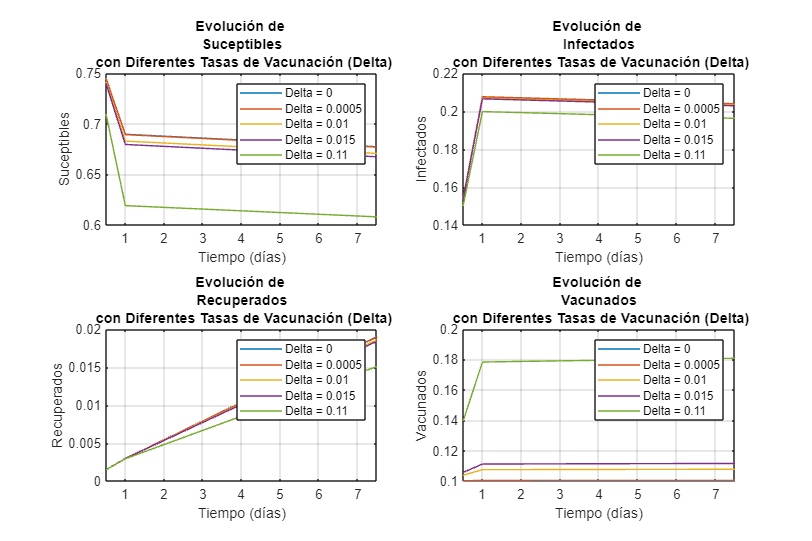

% Coeficientes o constantes del sistema (inicialmente, Delta es un valor base)
Beta = 1;  % Tasa de transmisión de la enfermedad
Delta_base = 0.01;     % Tasa de vacunación base
Gama = 0.02;      % Tasa de recuperación y aislamiento

% Valores de Delta para evaluar (al menos 5 valores diferentes, uno de ellos igual a cero)
delta_values = [0, 0.0005, 0.01, 0.015, 0.11];

% Espacio de muestreo para la invasión zombie
Ts = 1;           % Tiempo de muestreo en un día
tmin = 0;
tmax = 365;       % La enfermedad zombie en un año
tspan = [tmin, Ts, tmax];

% Inicializa una matriz para almacenar las soluciones de las variables con diferentes valores de Delta
soluciones = zeros(length(delta_values), length(tspan), 4);

% Resuelve el sistema de ecuaciones diferenciales para cada valor de Delta
for k = 1:length(delta_values)
    % Ajusta Delta para el valor actual
    Delta = delta_values(k);
    
    % Condiciones iniciales (mantenemos las mismas condiciones iniciales)
    s0 = 0.8;
    i0 = 0.1;
    r0 = 0;
    v0 = 0.1;
    C_iniciales_Zombies = [s0; i0; r0; v0];
    tasa_suceptibles_Zombies = @(t, s, i, r, v, beta) -beta * s * i - Delta * s;
    tasa_infectados_Zombies = @(t, s, i, r, v, beta) beta * i * s - Gama * i;
    tasa_recuperados_Zombies = @(t, s, i, r, v, beta) Gama * i;
    tasa_vacunados_Zombies = @(t, s, i, r, v, beta) Delta * s;
    
    % Resuelve el sistema de ecuaciones para este valor de Delta
    [tiempo, Salida] = ode45(@(t, y) [tasa_suceptibles_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_infectados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_recuperados_Zombies(t, y(1), y(2), y(3), y(4), Beta);
                                      tasa_vacunados_Zombies(t, y(1), y(2), y(3), y(4), Beta)], ...
                                      tspan, C_iniciales_Zombies);
    
    % Almacena las soluciones de todas las variables
    soluciones(k, :, :) = Salida;
end

% Tamaño de la figura
figure('Position', [100, 100, 1200, 800]);

variables = ["Suceptibles", "Infectados", "Recuperados", "Vacunados"];
for v = 1:4
    subplot(2, 2, v);
    for k = 1:length(delta_values)
        plot(tiempo, soluciones(k, :, v), 'DisplayName', ['Delta = ', num2str(delta_values(k))]);
        hold on;
        xlim([0.5,7.5])
    end
    grid on;
    xlabel("Tiempo (días)");
    ylabel(variables(v));
    title(['Evolución de ', variables(v), ' con Diferentes Tasas de Vacunación (Delta)']);
    legend('Location', 'northeast');
end


% Identificar la tasa mínima de vacunación para que el pico de infectados llegue a 0.2 (aumento del 100%)
tasa_minima_vacunacion = [];
for k = 1:length(delta_values)
    if any(soluciones(k, :, 2) <= 0.2)
        tasa_minima_vacunacion = delta_values(k);
        break; % Romper el bucle cuando se cumple la condición
    end
end

if isempty(tasa_minima_vacunacion)
    fprintf('No se encontró una tasa de vacunación para lograr el aumento del 100%% o mas en el pico de infectados.\n');
else
    fprintf('La tasa mínima de vacunación para lograr un pico de infectados mayor o igual 100%% es: %.4f\n', tasa_minima_vacunacion);
end

La tasa mínima de vacunación para lograr un pico de infectados del 100% es: 0.0000


#### Analisis de delta

En la vida real, la tasa de vacunación ($Delta$) puede ser modificada mediante una serie de estrategias implementadas por las autoridades de salud pública y los gobiernos. Estas estrategias incluyen campañas de vacunación masiva que promueven la inmunización, legislación que puede requerir la vacunación obligatoria para ciertas enfermedades, campañas de educación para informar al público sobre la importancia de las vacunas y la disipación de desinformación, así como la disponibilidad y acceso a vacunas en centros de atención médica y farmacias. Además, en situaciones de emergencia de salud pública o brotes de enfermedades contagiosas, se pueden implementar medidas más rigurosas para aumentar la tasa de vacunación como parte de una estrategia de contención.

#### Analisis del resultado

La simulación previa y el código asociado revelan que aumentar la tasa de vacunación ($`Delta$`) no resulta en un incremento en el número de infectados, sino que, contrariamente, reduce la cantidad de personas infectadas. Esto es evidente en los cuatro gráficos que representan las poblaciones de susceptibles, infectados, recuperados y vacunados. A medida que aumentamos el valor de $Delta$, observamos una disminución en el número de individuos infectados. En un escenario hipotético en el que la tasa de vacunación sea igual a cero, el valor máximo resultante sería el que produce el mayor número de personas infectadas.

Por esta razón, para abordar el problema y encontrar el valor de $Delta$ que limita los infectados al 20% de la población, se ajustó la tasa de propagación de la infección zombie. Se determinó que, con una tasa de infección igual a 1, $Delta$ debe ser al menos 0.106 para lograr que no más del 20% de la población se infecte. A medida que continuamos aumentando $Delta$, evitamos que una proporción aún mayor de la población sea afectada por el virus.

En los gráficos finales, se puede observar cómo variar $Delta$ afecta a cada variable. Por ejemplo, un aumento en $Delta$ conlleva una disminución en el número de susceptibles, ya que más personas pasan a ser vacunadas. De manera similar,la variable de personas recuperadas, ya que al haber mas individuos vacunados, abra menos individuos recuperados. Por ultimo, la variable de personas vacunadas aumenta a medida que $Delta$ se incrementa, ya que más individuos se vuelven vacunados en lugar de infectados

# Discusión y conlusión

A lo largo de este estudio, hemos explorado un modelo epidemiológico de propagación de una pandemia zombie mediante la resolución de ecuaciones diferenciales y el uso de MATLAB como herramienta clave. Hemos obtenido resultados significativos y coherentes que arrojan luz sobre cómo diversos parámetros afectan la dinámica de una epidemia zombie y su posible control. Al analizar y discutir estos resultados, podemos destacar varios puntos clave.

En primer lugar, hemos observado que la tasa de transmisión (Beta) desempeña un papel crítico en la propagación de la enfermedad. Cuando (Beta * S(0)) / Gama es menor que 1, la enfermedad tiende a disminuir con el tiempo, lo que tiene sentido desde una perspectiva epidemiológica. Esto refuerza la importancia de medidas de control, como la cuarentena y la vacunación, para reducir la tasa de transmisión y evitar la propagación incontrolada de la enfermedad.

Por otro lado, hemos visto que cambios en la tasa de vacunación (Delta) y la tasa de recuperación (Gama) también tienen un impacto significativo. Un aumento en Delta puede reducir el número de infectados, mientras que un aumento en Gama acelera la recuperación de los pacientes. Estos resultados son consistentes con estrategias de salud pública en situaciones de epidemia.

Sin embargo, es importante señalar que los resultados de este modelo epidemiológico son simplificados y dependen de suposiciones específicas. La dinámica de una pandemia zombie en la vida real es mucho más compleja y está sujeta a numerosos factores no considerados aquí, como la movilidad de la población, la respuesta del sistema de atención médica y las variaciones en la tasa de transmisión. Por lo tanto, estos resultados deben interpretarse como un punto de partida teórico más que como una representación exacta de una pandemia real.

En comparación con otros modelos epidemiológicos, nuestros resultados son específicos para la dinámica de una pandemia zombie y las características particulares de este escenario ficticio. Cada modelo epidemiológico se ajusta a un conjunto único de parámetros y suposiciones, y nuestros resultados reflejan las condiciones definidas en nuestro enfoque específico.

En resumen, este estudio nos ha proporcionado una visión valiosa sobre cómo los parámetros clave afectan la propagación de una pandemia zombie o una efermedad transmisible como lo fue el COVID-19 y cómo las estrategias de control pueden influir en el resultado. Si bien los resultados tienen sentido dentro del contexto del modelo, es importante recordar que las pandemias del mundo real son mucho más complejas y requieren un análisis más profundo y específico de las condiciones locales y globales.